%%% Going To Try To Build The Robot %%%%

kuka = rigidBodyTree("DataFormat","column");
base = kuka.Base;

rotatingBase = rigidBody("rotating_base");
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
arm4 = rigidBody("arm4");
arm5 = rigidBody("arm5");
gripper = rigidBody("gripper");



% Send Transform Matrix to the coll1.Pose function
% trvec2tform() takes in translation vector and gives us T matrix


% Define Poses Here:
collBase = collisionCylinder(0.7,0.159); % cylinder: radius,length
collBase.Pose = trvec2tform([0 0 0]);


coll1 = collisionCylinder(0.5, 0.341); 
coll1.Pose = trvec2tform([0 0 0]);
coll2 = collisionCylinder(0.2, .770); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([0 0 0]);
coll3 = collisionCylinder(0.15, .335); % box: length, width, height (x,y,z)
coll3.Pose = trvec2tform([0 0 0]);

coll4 = collisionCylinder(0.1, .300);
coll4.Pose = trvec2tform([0 0 0]);
% 
coll5 = collisionCylinder(0.25, .215)

coll5 =   collisionCylinder with properties:

    Radius: 0.2500
    Length: 0.2150
      Pose: [4×4 double]


coll5.Pose = trvec2tform([0 0 0]);
% 
% coll6
% col6.Pose



% collGripper = collisionSphere(0.15); % sphere: radius
% collGripper.Pose = trvec2tform([0 0 0]);


jntBase = rigidBodyJoint("base_joint","revolute");
jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jnt4 = rigidBodyJoint("jnt4","revolute");
jnt5 = rigidBodyJoint("jnt5","revolute");
jntGripper = rigidBodyJoint("gripper_joint","revolute");

% Define these manually in the home position
jnt1.JointAxis = [0 0 1]; % x-axis
jnt2.JointAxis = [1 0 0];
jnt3.JointAxis = [1 0 0];
jnt4.JointAxis = [1 0 0];
jnt5.JointAxis = [1 0 0];
jntGripper.JointAxis = [0 1 0] % y-axis

jntGripper =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'gripper_joint'
                 JointAxis: [0 1 0]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


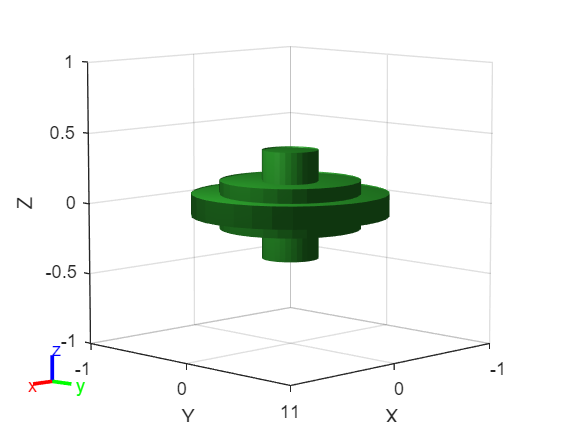



addCollision(rotatingBase,collBase)
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)
addCollision(arm4,coll4)
addCollision(arm5,coll5)
addCollision(gripper,collGripper)


% setFixedTransform(jnt1,trvec2tform([0.015 0 0.04]))
% setFixedTransform(jnt2,trvec2tform([-0.015 0 0.15]))
% setFixedTransform(jnt3,trvec2tform([0.015 0 0.15]))
% setFixedTransform(jntGripper,trvec2tform([0 0 0.15]))

bodies = {base,rotatingBase,arm1,arm2,arm3,arm4,arm5,gripper};
joints = {[],jntBase,jnt1,jnt2,jnt3,jnt4,jnt5,jntGripper};

for i = 2:length(bodies) % Skip base. Iterate through adding bodies and joints.
            bodies{i}.Joint = joints{i};
            addBody(kuka,bodies{i},bodies{i-1}.Name)
            show(kuka,"Collisions","on","Frames","off");
            drawnow;
end


disp(kuka)

  rigidBodyTree with properties:

     NumBodies: 7
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'rotating_base'  'arm1'  'arm2'  'arm3'  'arm4'  'arm5'  'gripper'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'



showdetails(kuka)  % this will help us debug

--------------------
Robot: (7 bodies)

 Idx            Body Name           Joint Name           Joint Type            Parent Name(Idx)   Children Name(s)
 ---            ---------           ----------           ----------            ----------------   ----------------
   1        rotating_base           base_joint             revolute                     base(0)   arm1(2)  
   2                 arm1                 jnt1             revolute            rotating_base(1)   arm2(3)  
   3                 arm2                 jnt2             revolute                     arm1(2)   arm3(4)  
   4                 arm3                 jnt3             revolute                     arm2(3)   arm4(5)  
   5                 arm4                 jnt4             revolute                     arm3(4)   arm5(6)  
   6                 arm5                 jnt5             revolute                     arm4(5)   gripper(7)  
   7              gripper        gripper_joint             revolute            

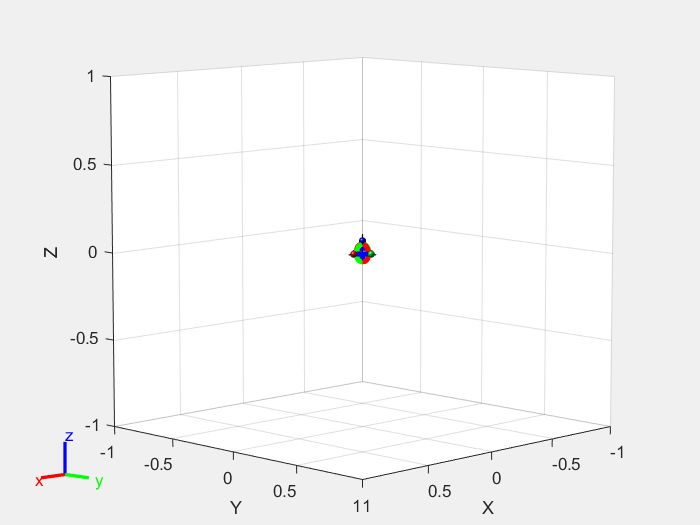


figure("Name","Interactive GUI")
gui = interactiveRigidBodyTree(kuka,"MarkerScaleFactor",0.25);